Семинар 4.

## Тема: "Регуляризация по Годунову плохообусловленной системы"

**Задание:** Дискретизировать интегральное уравнение $\int_b^a K\left(s,t\right)x\left(t\right)\mathrm{dt}=f\left(s\right),c\le s\le d$ и решить полученную СЛАУ применяя метод регуляризации по Годунову.

clc;
clear;

M = 51

M = 51

N = 91

N = 91

a = -16

a = -16

b = 16

b = 16

c = -16

c = -16

d = 16

d = 16


h_t = (b-a)/(M-1)

h_t = 0.6400

h_s = (d-c)/(N-1)

h_s = 0.3556


t = (a:h_t:b)'

t =   -16.0000
  -15.3600
  -14.7200
  -14.0800
  -13.4400
  -12.8000
  -12.1600
  -11.5200
  -10.8800
  -10.2400


s = (c:h_s:d)'

s =   -16.0000
  -15.6444
  -15.2889
  -14.9333
  -14.5778
  -14.2222
  -13.8667
  -13.5111
  -13.1556
  -12.8000



A = zeros(N, M);
for j = 1:N
    for i = 1:M
        if i > 1
            fun_1 = @(x) K_1(x,s(j)) .* (x - t(i - 1)) / h_t;
            A(j, i) = A(j, i) + integral(fun_1, t(i - 1), t(i));
        end
        if i < M
            fun_2 = @(x) K_1(x,s(j)) .* (t(i + 1) - x) / h_t;
            A(j, i) = A(j, i) + integral(fun_2, t(i), t(i + 1));
        end
    end
end
mu = cond(A)

mu = 8.0831e+36


F = f1(s, a, b)

F = 1.0e+16 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


B = zeros(M, M);
for j = 1:M
    for i = 1:M
        if abs(i - j) == 0
            B(i, j) = -2/h_t^2;
        end
        if abs(i - j) == 1
            B(i, j) = 1/h_t^2;
        end
    end
end

tau = 10^-1;
C = [(1 - tau)*A; tau*B]

C = 1.0e+13 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0003    0.0006    0.0011    0.0022    0.0041    0.0078    0.0148    0.0281    0.0533    0.1011    0.1918    0.3638    0.6899    1.3083    2.4813
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0004    0.0008    0.0015    0.0029    0.0055    0.0104    0.0197    0.0374    0.0709    0.1344    0.2549    0.4835    

cond(C)

ans = 3.1427e+16

F_reg = [(1 - tau)*F; zeros(M, 1)]

F_reg = 1.0e+16 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


x_comp = C\F_reg;

x_real = true_x_1(t)

x_real =   256.0000
  235.9296
  216.6784
  198.2464
  180.6336
  163.8400
  147.8656
  132.7104
  118.3744
  104.8576


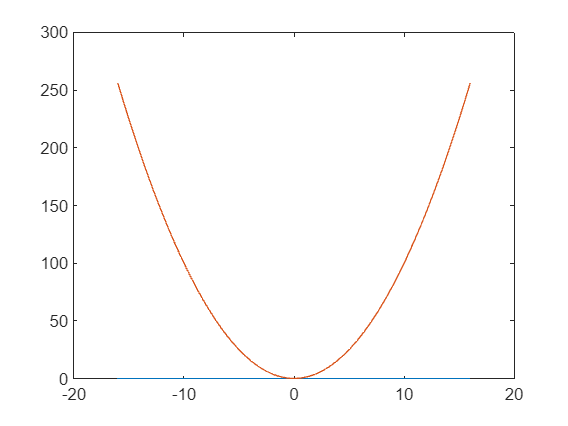


plot(t, x_comp)
hold on;
plot(t, x_real)
hold off;

function true_solution_1 = true_x_1(T);
    true_solution_1 = T.^2;
end

function true_solution_2 = true_x_2(T);
    true_solution_2 = exp(-T);
end

function K_first = K_1(t, s);
    K_first = exp(t - s);
end

function K_second = K_2(t, s);
    K_second = (t - s).^2;
end

function right_first = f1(S, a, b);
        right_first = ((b^2 - 2*b + 2)*exp(b) + (-(a^2) + 2*a - 2)*exp(a))*exp(S);
end

function right_second = f2(S, a, b);
        right_second = exp(-a)*(S.^2 + (-2*a - 2)*S + a^2 + 2*a + 2)...
            - exp(-b)*(S.^2 + (-2*b - 2)*S + b^2 + 2*b + 2);
end